**PROBLEMA 1**

m = 3;
t = 0:0.1:(2*pi)*m;
a = 2;
b = 13;
x = sin(a*t);
y = sin (b*t);
disp('         ****** PROBLEMA 1 *******         ');

         ****** PROBLEMA 1 *******         


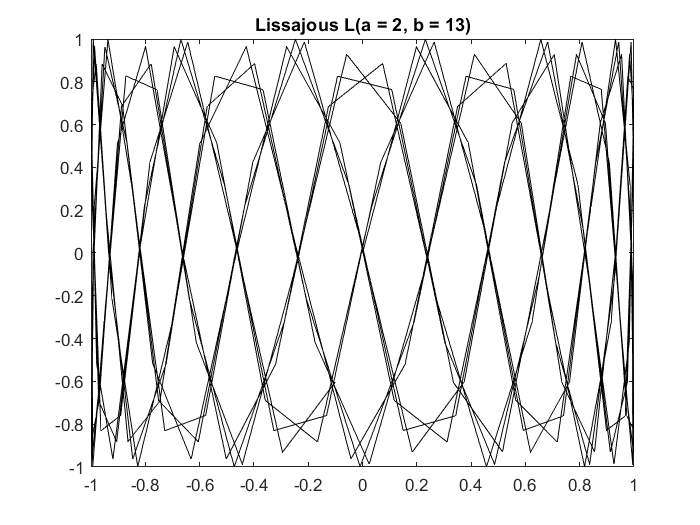

plot(x,y, '-k')
title('Lissajous L(a = 2, b = 13)');

figure

**PROBLEMA 2**

**a)**

m = 3;
t = 0:0.1:(2*pi)*m;
a = 7;
b = 3;
x = sin(a*t);
y = sin (b*t);
disp('         ****** PROBLEMA 2 *******         ');

         ****** PROBLEMA 2 *******         


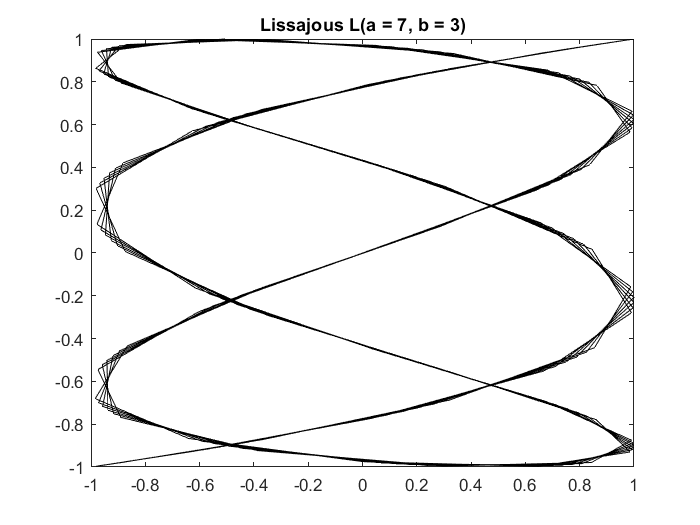

plot(x,y, '-k')
title('Lissajous L(a = 7, b = 3)');

figure


**b)**

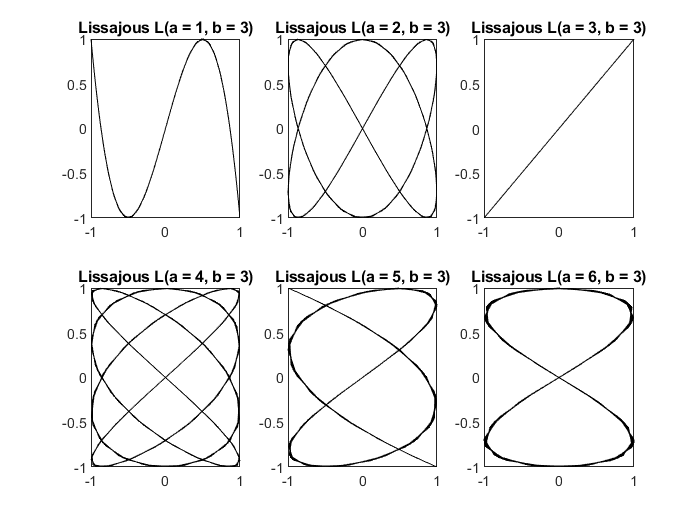

m = 3;
t = 0:0.1:(2*pi)*m;

a1 = 1;
a2 = 2;
a3 = 3;
a4 = 4;
a5 = 5;
a6 = 6;

b = 3;

x1 = sin(a1*t);
x2 = sin(a2*t);
x3 = sin(a3*t);
x4 = sin(a4*t);
x5 = sin(a5*t);
x6 = sin(a6*t);

y = sin(b*t);

figure

subplot(231)
plot(x1,y,'k')
title('Lissajous L(a = 1, b = 3)');

subplot(232)
plot(x2,y,'k')
title('Lissajous L(a = 2, b = 3)');

subplot(233)
plot(x3,y,'k')
title('Lissajous L(a = 3, b = 3)');

subplot(234)
plot(x4,y,'k')
title('Lissajous L(a = 4, b = 3)');

subplot(235)
plot(x5,y,'k')
title('Lissajous L(a = 5, b = 3)');

subplot(236)
plot(x6,y,'k')
title('Lissajous L(a = 6, b = 3)');


figure


**PROBLEMA 3**

m = 3;
t = 0:0.1:(2*pi)*m;
a = 7;
b = a + 1;
x = sin(a*t);
y = sin (b*t);
subplot(121);
disp('         ****** PROBLEMA 3 *******         ');

         ****** PROBLEMA 3 *******         


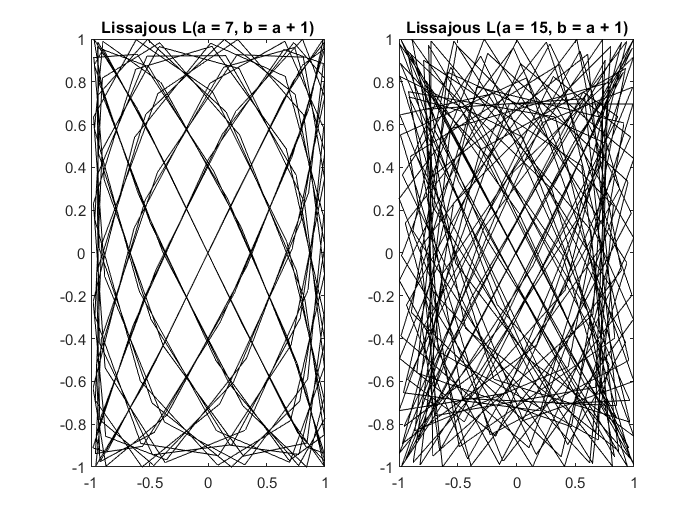

plot(x,y, '-k')
title('Lissajous L(a = 7, b = a + 1)');

m = 3;
t = 0:0.1:(2*pi)*m;
a = 15;
b = a + 1;
x = sin(a*t);
y = sin (b*t);
subplot(122);
plot(x,y, '-k')
title('Lissajous L(a = 15, b = a + 1)');


figure

**PROBLEMA 4**

disp('         ****** PROBLEMA 4 *******         ');

         ****** PROBLEMA 4 *******         


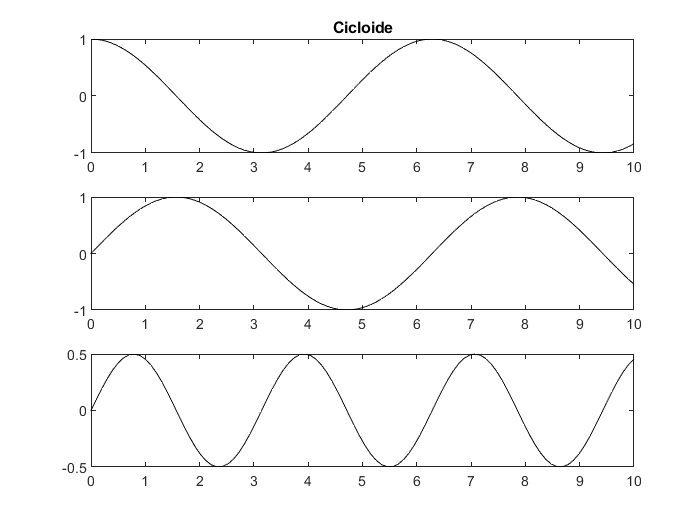


x = linspace(0,10,100);
 
figure(1);
 
subplot(3,1,1);
%  '3' means set up 3 graphs verticaly,
%  '1' means 1 graph wide, and the last
%  '1' means the first plot.
plot(x,cos(x),'k');
title('Cicloide');
 
subplot(3,1,2);
%  '2' for the second graph.
plot(x,sin(x),'k');
 
subplot(3,1,3);
plot(x,sin(x).*cos(x),'k');


figure


**PROBLEMA 5 Y 6**

disp('      ****** PROBLEMA 5 Y 6 *******         ');

      ****** PROBLEMA 5 Y 6 *******         


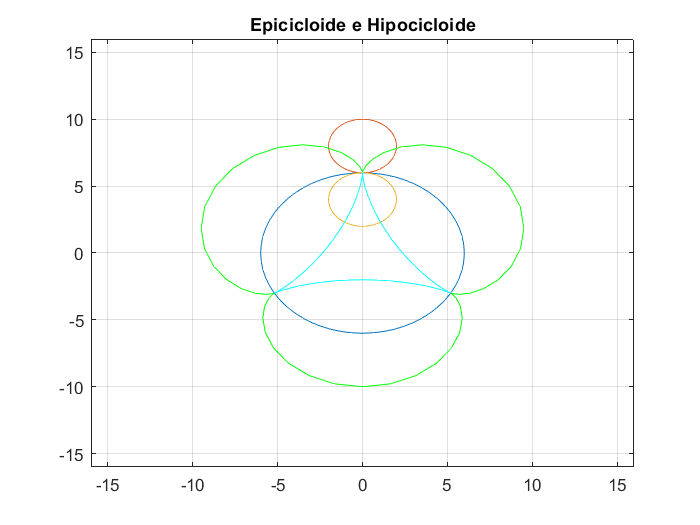


t=0:pi/30:2*pi;
R=6;r=2;
for k=1:length(t) 
%circulo mayor
xR=R*cos(t); 
yR=R*sin(t); 
%circulo menor afuera 
xr=r*sin(t)+(R+r)*sin(t(k));
yr=r*cos(t)+(R+r)*cos(t(k));
%circunferencia menor adentro
xr1=r*sin(t)+(R-r)*sin(t(k)); 
yr1=r*cos(t)+(R-r)*cos(t(k));
plot(xR,yR,xr,yr,xr1,yr1)
%epicicloide e hipocicloide
hold on 
x=(R+r)*sin(t)-r*sin(t*(1+R/r));
y=(R+r)*cos(t)-r*cos(t*(1+R/r)); 
x1=(R-r)*sin(t)+r*sin(t*(1-R/r)); 
y1=(R-r)*cos(t)+r*cos(t*(1-R/r));
plot(x(1:k),y(1:k),'-g',x1(1:k),y1(1:k),'-c')
hold off 
axis([-2*(R+r) 2*(R+r) -2*(R+r) 2*(R+r)])
grid on 
title('Epicicloide e Hipocicloide')
pause(0.01)
end